# MAT-63506 Scientific computing, Solutions for exercise set 2

# Mar 12-18, 2018

## Exercise 1

See the code at the end of the file.

Evaluate the function at the given arguments.

M = magic(7);
A1 = normalize_cols(M, 1)

A1 =     0.1714    0.2229    0.2743    0.0057    0.0571    0.1086    0.1600
    0.2171    0.2686    0.0400    0.0514    0.1029    0.1543    0.1657
    0.2629    0.0343    0.0457    0.0971    0.1486    0.2000    0.2114
    0.0286    0.0800    0.0914    0.1429    0.1943    0.2057    0.2571
    0.0743    0.0857    0.1371    0.1886    0.2400    0.2514    0.0229
    0.1200    0.1314    0.1829    0.2343    0.2457    0.0171    0.0686
    0.1257    0.1771    0.2286    0.2800    0.0114    0.0629    0.1143


A2 = normalize_cols(M)

A2 =     0.4016    0.5176    0.6263    0.0127    0.1305    0.2522    0.3749
    0.5088    0.6238    0.0913    0.1146    0.2349    0.3583    0.3883
    0.6159    0.0796    0.1044    0.2165    0.3393    0.4645    0.4954
    0.0669    0.1858    0.2088    0.3183    0.4437    0.4778    0.6025
    0.1740    0.1991    0.3132    0.4202    0.5480    0.5840    0.0536
    0.2812    0.3053    0.4176    0.5221    0.5611    0.0398    0.1607
    0.2945    0.4114    0.5220    0.6240    0.0261    0.1460    0.2678


A3 = normalize_cols(M, 7.3)

A3 =     0.6292    0.7997    0.9624    0.0196    0.2108    0.4104    0.5994
    0.7969    0.9637    0.1404    0.1765    0.3794    0.5832    0.6208
    0.9647    0.1230    0.1604    0.3334    0.5480    0.7560    0.7920
    0.1049    0.2871    0.3208    0.4904    0.7167    0.7776    0.9633
    0.2726    0.3076    0.4812    0.6473    0.8853    0.9504    0.0856
    0.4404    0.4716    0.6416    0.8042    0.9064    0.0648    0.2569
    0.4614    0.6356    0.8020    0.9611    0.0422    0.2376    0.4281


A4 = normalize_cols(M, 42)

A4 =     0.6522    0.8298    1.0000    0.0204    0.2308    0.4318    0.6222
    0.8261    1.0000    0.1458    0.1837    0.4155    0.6136    0.6444
    1.0000    0.1277    0.1667    0.3469    0.6001    0.7954    0.8222
    0.1087    0.2979    0.3333    0.5102    0.7848    0.8182    1.0000
    0.2826    0.3191    0.5000    0.6735    0.9694    1.0000    0.0889
    0.4565    0.4894    0.6667    0.8367    0.9925    0.0682    0.2667
    0.4783    0.6596    0.8333    1.0000    0.0462    0.2500    0.4444


A5 = normalize_cols(M, Inf)

A5 =     0.6522    0.8298    1.0000    0.0204    0.2326    0.4318    0.6222
    0.8261    1.0000    0.1458    0.1837    0.4186    0.6136    0.6444
    1.0000    0.1277    0.1667    0.3469    0.6047    0.7955    0.8222
    0.1087    0.2979    0.3333    0.5102    0.7907    0.8182    1.0000
    0.2826    0.3191    0.5000    0.6735    0.9767    1.0000    0.0889
    0.4565    0.4894    0.6667    0.8367    1.0000    0.0682    0.2667
    0.4783    0.6596    0.8333    1.0000    0.0465    0.2500    0.4444


## Exercise 2

See the code at the end of the file.

Plot the error

x2 = 0:0.01:10;
y2 = sqrt_square(x2, 50);
plot(x2, x2 - y2)

Add axis labels and a title

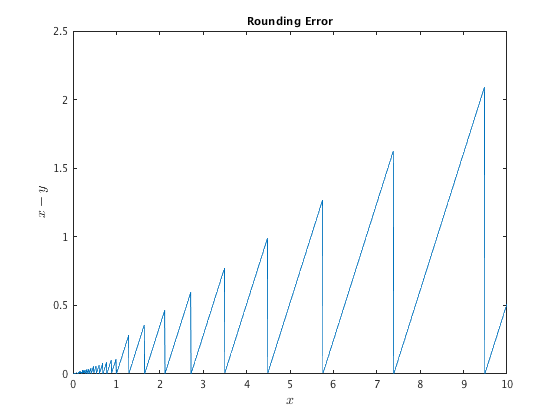

xlabel('$x$', 'Interpreter', 'latex', 'Fontsize', 14)
ylabel('$x - y$', 'Interpreter', 'latex', 'Fontsize', 14)
title('Rounding Error')

## Exercise 3

Make a handle to the function

f = @(x) log(x)./(x - 1)

f = function_handle with value:
    @(x)log(x)./(x-1)


Set tolerances

tol = 10.^(-(1:18));
n = length(tol)

n = 18

Allocate space for `y3`

y3 = zeros(1,n);

Compute the integrals

for k = 1:n
    y3(k) = integral(f, 0, 1, 'RelTol', tol(k), 'AbsTol', tol(k));
end

Compute the error and plot its absolute value.

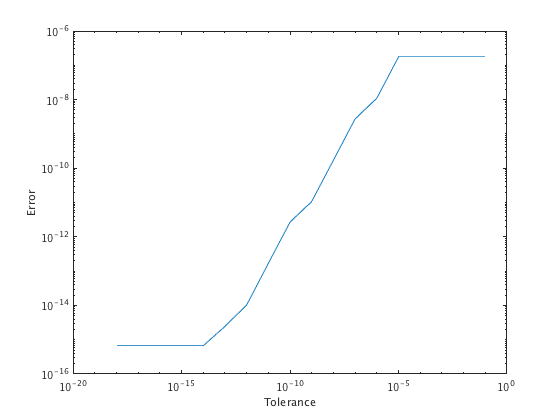

err3 = pi^2/6 - y3;
figure
loglog(tol, abs(err3))
xlabel('Tolerance'); ylabel('Error')

## Exercise 4

Call the function giving the filename *ShootInFoot.txt* as an argument. Calling the function without arguments opens the standard open file dialog box.

s = file2cellstr('ShootInFoot.txt');

Since `s` is a row cell array, we transpose it to column, so we can view the contents more conveniently.

s'

ans = 97×1 cell array
    {'Shooting  Yourself  in  the  Foot'                                                                                                      }
    {'	The proliferation of modern programming languages (all of which seem to'                                                            }
    {'have stolen countless features from each other) sometimes makes it'                                                                     }
    {'difficult to remember what language you're currently using.  This guide'                                                                }
    {'is offered as a public service to help programmers who find themselves in'                                                              }
    {'such a dilemma.'                                                                                                                        }
    {'C:  You shoot yourself in the foot.'                                                                           

## Exercise 5

Load the file `teststrings.mat`, which defines the cell array of strings `strings`. Call the function with `strings` and the filename *ShootInFoot1.txt* as an arguments. Calling the function with only `strings` as argument opens the standard save file dialog box.

load teststrings.mat
cellstr2file(strings, 'ShootInFoot1.txt')

Check by typing the file

type ShootInFoot1.txt


Shooting  Yourself  in  the  Foot
	The proliferation of modern programming languages (all of which seem to
have stolen countless features from each other) sometimes makes it
difficult to remember what language you're currently using.  This guide
is offered as a public service to help programmers who find themselves in
such a dilemma.
C:  You shoot yourself in the foot.
C++:  You accidentally create a dozen instances of yourself and shoot
them all in the foot.  Providing emergency medical assistance is
impossible since you can't tell which are the bitwise copies and which
are just pointing at others and saying, "That's me, over there."
FORTRAN:  You shoot yourself in each toe, iteratively, until you run out
of toes, then you read in the next foot and repeat.  If you run out of
bullets, you continue anyway because you have no exception handling
ability.
Modula-2:  After realizing that you can't actually accomplish anything in
this language, you shoot yourself in the head.
COBOL:  USEing

## Exercise 6

Compute and plot the approximation to the Cantor function for `n = 8`.

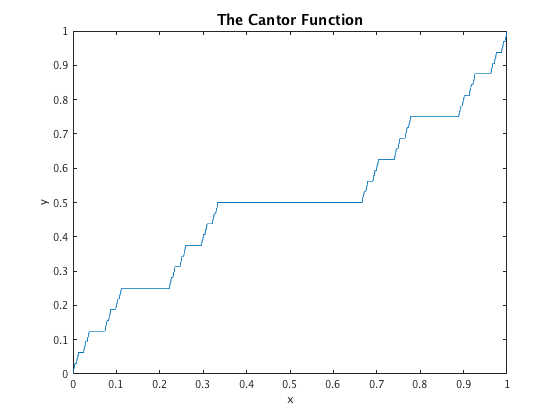

x6 = 0:0.001:1;
y6 = cantor(x6, 8);
figure
plot(x6, y6)
xlabel('x'); ylabel('y')
title('The Cantor Function', 'FontSize', 14)

function A = normalize_cols(A, p)
% NORMALIZE_COLS normalizes the columns of a matrix.

    narginchk(1, 2);
    
    assert(ismatrix(A), 'The argument must be a matrix');
    
    if nargin == 1, p = 2; end
    
    n = size(A, 2);
    
    for j = 1:n
        Aj = A(:, j);
        A(:, j) = Aj/norm(Aj, p);
    end
end


function x = sqrt_square(x, n)
% SQRT_SQUARE Repeated squarerooting and squaring
%	sqrt_square(x, n) takes the square root of x n times and
%	then squares the result n times. x can be an array.

    assert(all(x(:) >= 0),...
    	'The first argument must be a nonnegative array.');
    
    assert(n > 0 && n == round(n),...
    	'The second argument must be a positive integer.')
    
    for i = 1:n
        x = sqrt(x);
    end
    
    for i = 1:n
        x = x.^2; % Elementwise power
    end
end


function s = file2cellstr(filename)
% FILE2CELLSTR reads nonempty lines from a file
%
%  s = file2cellstr(filename) reads the nonempty lines from the file
%  'filename' and returns them in the cell array s. If filename is not
%  given, the standard open file dialog box is opened.

    narginchk(0, 1);
    
    % If filename is not given, show the standard open file dialog box
    if nargin == 0
    	[filen, pathn] = uigetfile('*.txt', 'Choose a text file');
    	assert(ischar(filen), 'No file selected.');
    	filename = fullfile(pathn, filen);
    end
    
    % Open the file for reading in text mode
    [fid, message] = fopen(filename, 'rt');
    assert(fid >= 0, message); % Check that it worked
    
    % Initialize s and read the first line
    s = {};
    aline = fgetl(fid);
    % Loop until end of file is reached
    while ischar(aline)
        if ~isempty(aline)
            s{end + 1} = aline; %#ok<*AGROW>
        end
            aline = fgetl(fid);
    end
    
    fclose(fid); % Close the file
end


function cellstr2file(strings, filename)
% CELLSTR2FILE writes strings from a cell array into a file.
%
%  cellstr2file(strings, filename) writes each string in the cell array
%  'strings' to file 'filename' as a separate line. If filename is not
%   given, the standard save file dialog box is opened.

    narginchk(1, 2);
    assert(iscellstr(strings),...
    	'The first argument must be a cell array of strings');
    
    % If filename is not given, open the standard save file dialog box
    if nargin == 1
        [filen, pathn] = uiputfile('', 'Save the file as',...
            'ShootInFoot1.txt');
        assert(ischar(filen), 'No file selected.');
        filename = fullfile(pathn, filen);
    else
        assert(ischar(filename), 'The second argument must be a string');
    end
    
    % Open (or create) the file in text mode for writing
    [fid, message] = fopen(filename, 'wt');
    assert(fid >= 0, message); % Check that it worked
    
    % Write the strings to the file
    for k = 1:numel(strings)
        fprintf(fid, '%s\n', strings{k});
    end
    
    fclose(fid); % Close the file
end


function y = cantor(x, n)
% CANTOR Computes the Cantor function aka the devil's staircase.
%
%  y = cantor(x, n) computes the nth approximation to the Cantor
%  function at x, which can be an array.

    assert(n >= 0 && n == round(n),...
    	'The argument n must be a nonnegative integer.');
    
    assert(all(x(:) >= 0 & x(:) <= 1), 'x must be in the interval [0, 1]')
    
    y = zeros(size(x));  % Initialize to the same size as x
    for k = 1:numel(x)
        y(k) = cantor_aux(x(k), n);
    end
end

% Instead of the for loop above you could use the following
% y = arrayfun(@(x) cantor_aux(x, n), x), although it is slower.

function y = cantor_aux(x, n)
% y = cantor_aux(x, n) computes the nth approximation to the
% Cantor function at scalar x.

    % We know that x >= 0 and x <= 1
    if n == 0
        y = x;
    elseif x <= 1/3
        y = 0.5*cantor_aux(3*x, n - 1);
    elseif x <= 2/3
        y = 0.5;
    else
        y = 0.5 + 0.5*cantor_aux(3*x - 2, n - 1);
    end
end